# **JacobiEpsilon**

Jacobi second form of the elliptic integral of the second kind  or [Jacobi's Epsilon Function](https://dlmf.nist.gov/22.16#ii)

## Definition


$$\epsilon \left(x\left|m\right.\right)\equiv \int_0^x {\textrm{dn}}^2 \left(t\left|m\right.\right)\;\mathit{dt}$$



$$\varepsilon \left(x,k\right)\equiv \varepsilon \left(x\left|k^2 \right.\right)$$


where *k *is the modulus and *m *is the parameter. 

Domain: If $-\infty <m\le 1$ (or $|k|\le 1$) then $-\infty \le x\le \infty$. If $m>1$ then  $|x|<K\left(m^{-1} \right)/\sqrt{m}$. For the specified domain, the  codomain is the set of real numbers.

Basic features:

$\varepsilon \left(-x\left|m\right.\right)=-\varepsilon \left(x\left|m\right.\right)$   (odd) 

 $\varepsilon \left(2\mathit{nK}\pm x\left|m\right.\right)=2\mathit{nE}\left(m\right)\pm \varepsilon \left(x\left|m\right.\right),\;\;\;|x|\le K\left(m\right)$  (quasi-periodic)

$\varepsilon \left(x\left|m\right.\right)=\mathit{\mathbf{E}}\left(\mathrm{sn}\left(x|m\right)|m\right),\;|x|\le K\left(m\right)$,    $\varepsilon \left(x\left|m\right.\right)=E\left(\textrm{am}\left(x\left|m\right.\right)\left|m\right.\right)$

Special values:

$\varepsilon \left(0\left|m\right.\right)=0$,   $\varepsilon \left(K\left(m\right)\left|m\right.\right)=E\left(m\right)$

$\epsilon \left(x\left|-\infty \right.\right)=\mathrm{sign}\left(x\right)\infty$,   $\epsilon \left(x\left|0\right.\right)=x$,  $\epsilon \left(x\left|1\right.\right)=\mathrm{tanh}\left(x\right)$,    $\epsilon \left(x\left|\infty \right.\right)=0$

Identities:


$$\epsilon \left(x+2K\left(m\right)\left|m\right.\right)=\epsilon \left(x\left|m\right.\right)+2E\left(m\right)$$



$$\epsilon \left(x\left|m\right.\right)=\sqrt{m}\epsilon \left(x\sqrt{m}\left|m^{-1} \right.\right)+\left(1-m\right)x,\;\;\;\;m>1$$


$\mathit{\mathbf{E}}\left(x\left|m\right.\right)$ is Jacobi form of elliptic integral of second kind,$E\left(\phi \left|m\right.\right)$ is Legendre form of elliptic integral of the second kind, $K\left(m\right)$ and $E\left(m\right)$ are complete elliptic integrals of the first and the second kind.

## Syntax

Y = JacobiEpsilon(X,K)

y = jepsilon(x,k)

Y = mJacobiEpsilon(X,M)

y = mjepsilon(x,m)

## Description

**Y = JacobiEpsilon(X,K)** returns the Jacobi elliptic function $\epsilon \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **JacobiEpsilon** is the wrapper function which calls the functions **jepsilon** element-wise via the function **ufun2**.

**y = jepsilon(x,k)** returns the Jacobi elliptic function $\epsilon \left(x,k\right)$ for argument x and the modulus k. It is assumed that  the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed. **jepsilon** is the wrapper function which calls the functions mjepsilon.

**Y = mJacobiEpsilon(X,M) **returns the Jacobi elliptic function $\varepsilon \left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mJacobiEpsilon** is the wrapper function which calls the function **mjepsilon** element-wise via the function **ufun2**.

**y = mjepsilon(x,m) **returns the Jacobi elliptic function $\varepsilon \left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real scalars without check. y is NaN if any of  the arguments is invalid or convergence failed.   **mjepsilon** calculte  $\varepsilon \left(x\left|m\right.\right)$ using the functions , **melE**,** melK, mjsn **and** mjzeta  **([1])

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5; % |k|<= 1
x = 0.5;
[jepsilon(x,k), JacobiEpsilon(x,k), mjepsilon(x,k^2), mJacobiEpsilon(x,k^2)]

ans =    0.490202745772433   0.490202745772433   0.490202745772433   0.490202745772433


Accuracy

fprintf('%.16g\n',jepsilon(0.5,0.5))

0.490202745772433


% Maple  0.490202745772433_228

Special values

m = -20;
x = -0.5;  % |x| <= 1
mjepsilon(0,m)

ans = 0

disp(mjepsilon(melK(m),m) - melE(m))  % m < 1 !!!

     0



disp(mjepsilon(x,0) - x)  

     0



disp(mjepsilon(x,1) - tanh(x))

     0



mjepsilon(x,inf)

ans = 0

mjepsilon(-x,-inf)

ans = Inf

Identities

m = -2; 
x = 0.5; % |x| <= 1
mJacobiEpsilon(-x,m) + mJacobiEpsilon(x,m) % odd function

ans = 0

disp(mJacobiEpsilon(x,m) - mpEllipticE(mjam(x,m),m))  % definition

     1.110223024625157e-16



m = -2; % |m| < 1
disp(mjepsilon(x,m) - melE(mjsn(x,m),m))  % usual definition

     0



k = 0.5;
disp(jepsilon(x+2*elK(k),k)-jepsilon(x,k)-2*elE(k))  % 22.16.29 from NIST Handbook

     0



**Vector input**

x = [ 1, 2, 4];
k = [-0.1, .1, 0.9999];
disp(JacobiEpsilon(x+2*EllipticK(k),k)-...
    JacobiEpsilon(x,k)-2*EllipticE(k))  % 22.16.29 from NIST Handbook

     0     0     0



**Matrix input**

X = [ 1, 2, 4; -2, -3, -4];
m = [-0.1, .1, 0.9999; -10, -20, -30];
disp(mJacobiEpsilon(X+2*mEllipticK(m),m) - ...
    (mJacobiEpsilon(X,m)+2*mEllipticE(m)))  % 22.16.29 from NIST Handbook

   1.0e-13 *

                   0  -0.008881784197001                   0
   0.006661338147751  -0.017763568394003   0.106581410364015



## **Graphs **

**Example 1**

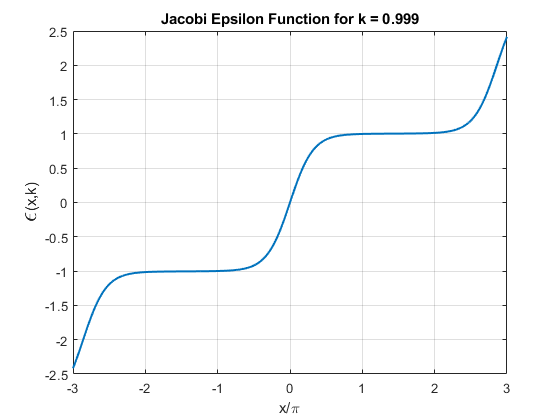

figure
x=-3:0.01:3;
k = 0.999;
plot(x,JacobiEpsilon(pi*x,k),'LineWidth',1.5)
xlabel('x/\pi')
ylabel('\fontsize{19}\epsilon\fontsize{11}(x,k)')
title(sprintf('Jacobi Epsilon Function for k = %g',k))
grid on

**Example 2**

Example from NIST Mathematical Functions Handbook (Fig 22.16.2)

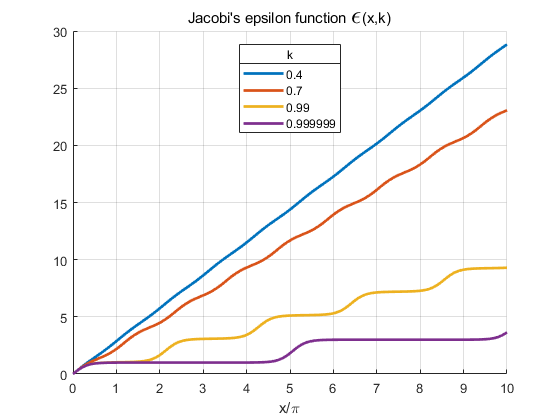

figure
clf
hold on
npts = 100;
k = [0.4, 0.7, 0.99, 0.999999];
s = pi;
xlim =  10;
x = linspace( 0, xlim, npts);
xx = x*s;
nn = length(k);
txt{nn}=[];
for n = 1:nn
    txt{n} = num2str(k(n),6);
    plot(x,JacobiEpsilon(xx,k(n)),'LineWidth',2)
end
hlg = legend(txt,'Location','best');
title(hlg, 'k','FontWeight','normal')
xlabel('x/\pi')
ylim([0, 30]);
title('Jacobi''s epsilon function \fontsize{19}\epsilon\fontsize{11}(x,k)','FontWeight','normal')
grid on
hold off

**Example 3**

figure
X = -6:0.1:6;
M = -1.5:0.5:1.5;
EPS = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    EPS(i,:) = mJacobiEpsilon(X,M(i));
end
plot(X,EPS,'LineWidth',1.5)
%axis([min(X) max(X) -1.2 1.2])
grid on
legend(clg,'Location','Best')

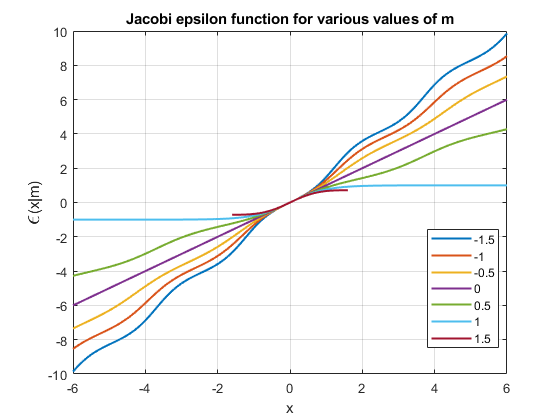

title('Jacobi epsilon function for various values of m')
xlabel('x')
ylabel('\epsilon(x|m)')
ylabel(strcat('\fontsize{19}\epsilon\fontsize{11}(x|m)'));

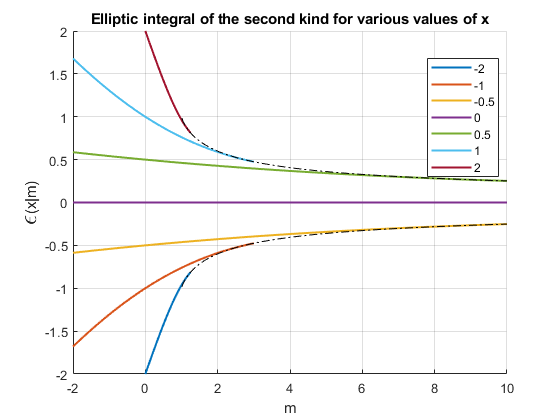

figure
hold on
M = -2:0.01:10;
X = [-2,-1,-0.5,0,0.5,1,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mJacobiEpsilon(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Elliptic integral of the second kind for various values of x')
xlabel('m')
ylabel('\fontsize{19}\epsilon\fontsize{11}(x|m)')
M = 0:0.01:10;
F = mJacobiEpsilon(mEllipticK(1./M)./sqrt(abs(M)),M);
plot(M,F,'k-.')
plot(M,-F,'k-.')
ylim([-2 2])
hold off

**Example 4**

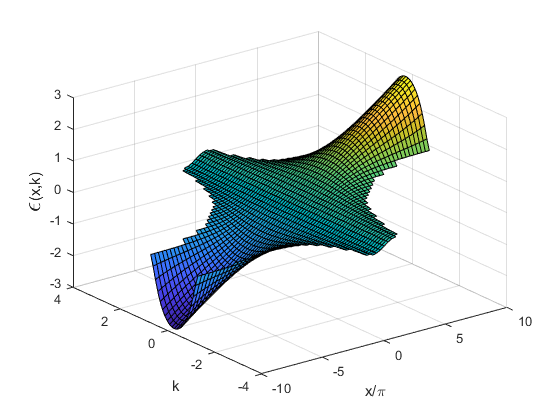

figure
x=-3:0.1:3;
k=-4:0.1:4;
[X,K]=meshgrid(x,k);
surface(pi*X,K,JacobiEpsilon(X,K))
view(3)
xlabel('x/\pi')
ylabel('k')
zlabel('\fontsize{19}\epsilon\fontsize{11}(x,k)')
grid on

**Example 5**

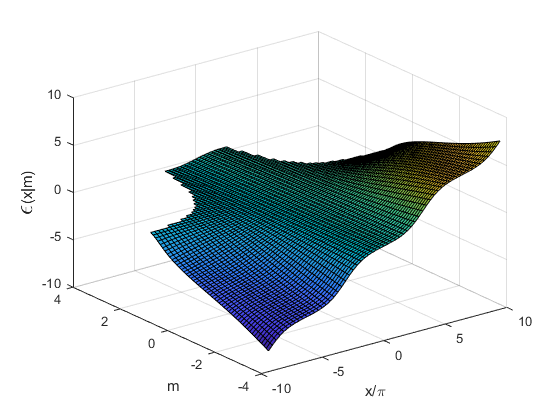

figure
x=-3:0.1:3;
m=-4:0.1:4;
[X,M]=meshgrid(x,m);
surface(pi*X,M,mJacobiEpsilon(X,M))
view(3)
xlabel('x/\pi')
ylabel('m')
zlabel('\fontsize{19}\epsilon\fontsize{11}(x|m)')
grid on

**Example 6**

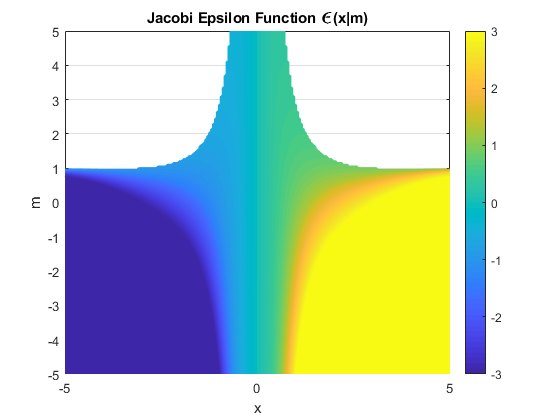

figure
f = @(x,m)mJacobiEpsilon(x,m);
fcontour(f,'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Jacobi Epsilon Function \fontsize{19}\epsilon\fontsize{11}(x|m)')
xlabel('x')
ylabel('m')
colorbar
grid on

**Example 7**

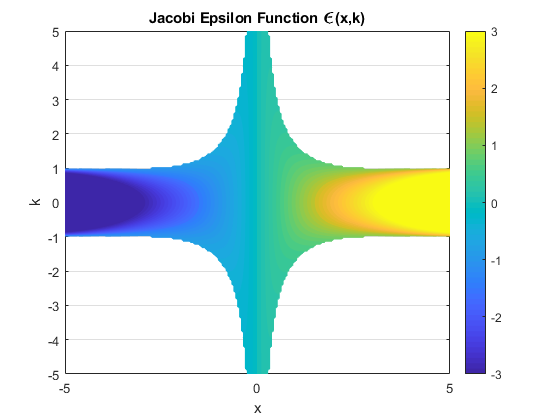

figure
f = @(x,k)JacobiEpsilon(x,k);
fcontour(f,'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Jacobi Epsilon Function \fontsize{19}\epsilon\fontsize{11}(x,k)')
xlabel('x')
ylabel('k')
colorbar
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions, part III. Numerische Mathematik 13, 305-315, 1969

## See Also